# Dataset Testing

## Acoustic data

% Load variables
x0Nm_Normal = load("C:\Users\giljo\Desktop\Master\CBIIoT-Framework\Data\IM\acoustic\0Nm_Normal.mat");
acData = x0Nm_Normal.Signal;
clear x0Nm_Normal;

% Display results
acData

acData = struct with fields:
           x_values: [1×1 struct]
           y_values: [1×1 struct]
    function_record: [1×1 struct]


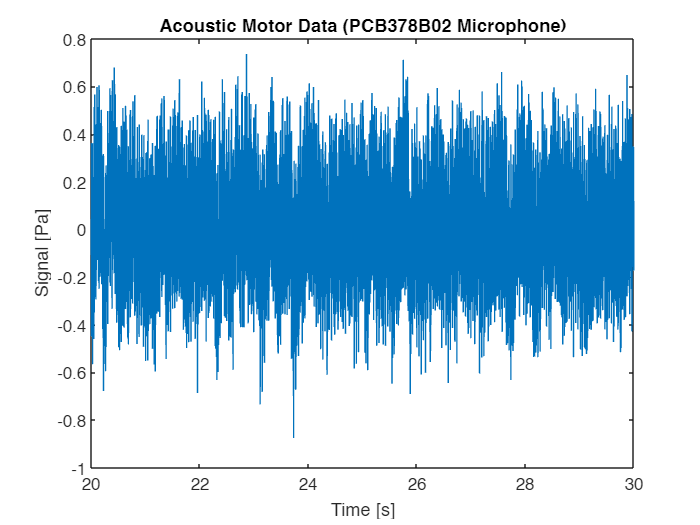

startv = acData.x_values.start_value;
incre = acData.x_values.increment;
N = acData.x_values.number_of_values;

tstamp = startv + incre*(0:N-1);

close all
plot(tstamp, acData.y_values.values)
xlabel('Time [s]')
ylabel('Signal [Pa]')
title('Acoustic Motor Data (PCB378B02 Microphone)')
xlim([20,30])

audiowrite('Audio.wav',acData.y_values.values,51200,'BitsPerSample',16)
    

## Vibration Data

% Load variables
x0Nm_Normal2 = load("C:\Users\giljo\Desktop\Master\CBIIoT-Framework\Data\IM\vibration\0Nm_Normal.mat");
vibData = x0Nm_Normal2.Signal;
clear x0Nm_Normal2;

% Display results
vibData

vibData = struct with fields:
           x_values: [1×1 struct]
           y_values: [1×1 struct]
    function_record: [1×1 struct]


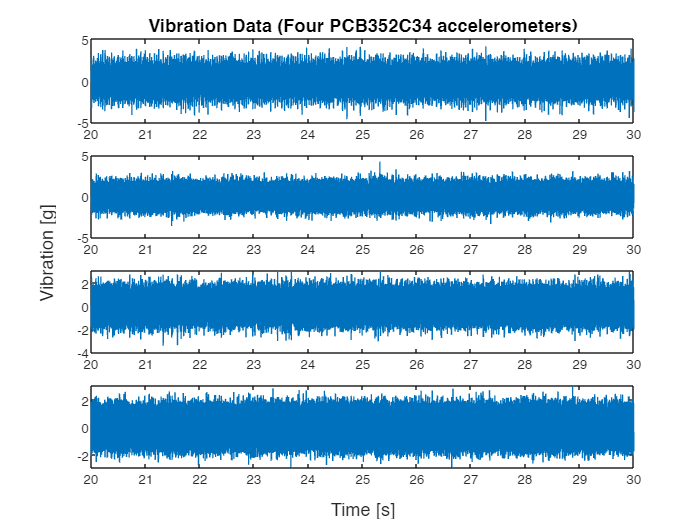

startv2 = vibData.x_values.start_value;
incre2 = vibData.x_values.increment;
N2 = vibData.x_values.number_of_values;

tstamp2 = startv2 + incre2*(0:N2-1);

fig = figure;

subplot(4,1,1);
plot(tstamp2, vibData.y_values.values(:,1))
xlim([20,30])
subplot(4,1,2);
plot(tstamp2, vibData.y_values.values(:,2))
xlim([20,30])
subplot(4,1,3);
plot(tstamp2, vibData.y_values.values(:,3))
xlim([20,30])
subplot(4,1,4);
plot(tstamp2, vibData.y_values.values(:,4))
xlim([20,30])

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Vibration [g]');
xlabel(han,'Time [s]');
title(han,'Vibration Data (Four PCB352C34 accelerometers)');

hold off

## Temp and Current Data

tempCurrData_0Nm_BPFI_03 =  tdmsread('W:\Git\major-cbs-framework\Data\IM\current,temp\0Nm_BPFI_03.tdms')

tempCurrData_0Nm_BPFI_03 = 1×2 cell array
    {0×0 table}    {1536492×5 table}


tempCurrData_0Nm_BPFI_10 =  tdmsread('W:\Git\major-cbs-framework\Data\IM\current,temp\0Nm_BPFI_10.tdms')

tempCurrData_0Nm_BPFI_10 = 1×2 cell array
    {0×0 table}    {1536492×5 table}


tempCurrData_0Nm_BPFO_03 =  tdmsread('W:\Git\major-cbs-framework\Data\IM\current,temp\0Nm_BPFO_03.tdms')

tempCurrData_0Nm_BPFO_03 = 1×2 cell array
    {0×0 table}    {1536492×5 table}


tempCurrData_0Nm_BPFO_10 =  tdmsread('W:\Git\major-cbs-framework\Data\IM\current,temp\0Nm_BPFO_10.tdms')

tempCurrData_0Nm_BPFO_10 = 1×2 cell array
    {0×0 table}    {1536492×5 table}


tempCurrData = tempCurrData_0Nm_BPFO_10

tempCurrData = 1×2 cell array
    {0×0 table}    {1536492×5 table}


tempCurrData = tempCurrData{2}

tempCurrData = 1536492×5 table
    cDAQ9185-1F486B5Mod1/ai0    cDAQ9185-1F486B5Mod1/ai1    cDAQ9185-1F486B5Mod2/ai0    cDAQ9185-1F486B5Mod2/ai2    cDAQ9185-1F486B5Mod2/ai3
    ________________________    ________________________    ________________________    ________________________    ________________________

             28.661                      29.024                     -2.8507                       NaN                         NaN           
             28.661                      29.024                     -2.7849                       NaN                         NaN           
             28.661                      29.024                     -2.7108                       NaN                         NaN           
             28.661                      29.024                     -2.5545                  

tempCurrData = table2array(tempCurrData)

tempCurrData =    28.6612   29.0241   -2.8507       NaN       NaN
   28.6612   29.0241   -2.7849       NaN       NaN
   28.6612   29.0241   -2.7108       NaN       NaN
   28.6612   29.0241   -2.5545       NaN       NaN
   28.6612   29.0241   -2.6080       NaN       NaN
   28.6612   29.0241   -2.8000       NaN       NaN
   28.6612   29.0241   -2.8123       NaN       NaN
   28.6612   29.0241   -2.9481       NaN       NaN
   28.6612   29.0241   -2.7410       NaN       NaN
   28.6612   29.0241   -2.5915       NaN       NaN


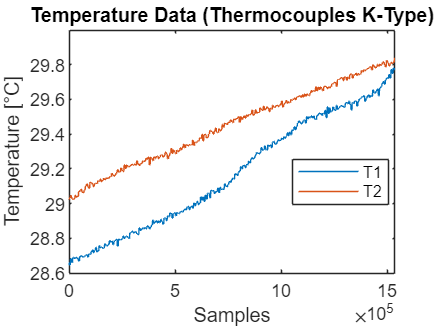

figure
plot(tempCurrData(:,1:2))
legend('T1','T2',"Location","best")
title('Temperature Data (Thermocouples K-Type)')
ylabel('Temperature [°C]')
xlabel('Samples')

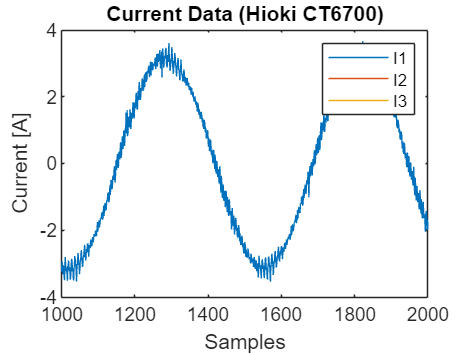

figure
plot(tempCurrData(:,3:5))
legend('I1','I2','I3')
title('Current Data (Hioki CT6700)')
ylabel('Current [A]')
xlabel('Samples')
xlim([1000,2000])